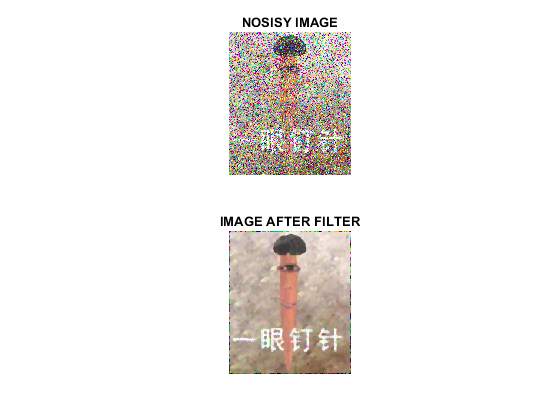

% median_filter
image_variable=imread('yydz.jpg');
N=imnoise(image_variable,"salt & pepper",0.3);

red_channel=N(:,:,1);
green_channel=N(:,:,2);
blue_channel=N(:,:,3);

red_channel=medfilt2(red_channel,[5,5]);
green_channel=medfilt2(green_channel,[5,5]);
blue_channel=medfilt2(blue_channel,[5,5]);

% CAT CONCENTRATE ARRAY
F=cat(3,red_channel,green_channel,blue_channel);

subplot(2,1,1),imshow(N),title('NOSISY IMAGE');
subplot(2,1,2),imshow(F),title('IMAGE AFTER FILTER');